1`

**DEPARTMENT OF ELECTRONIC AND COMMUNICATION ENGINEERING**

**2ECDE51- IMAGE PROCESSING**

**SPECIAL ASSIGNMENT**

**Date:** 09/11/2023                                                                                                                                        **ROLL NO.:**  21BEC052 

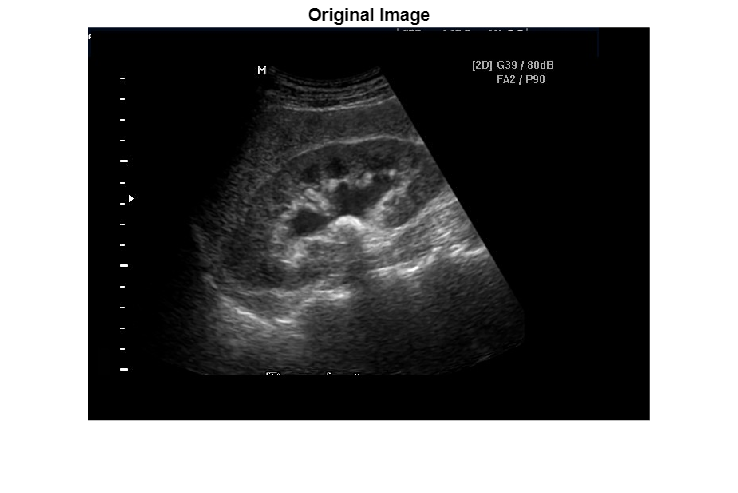

clc;
clear all;
close all;
%Choose image file
[filename,pathname]=uigetfile('*.*','Pick a MATLAB code file');
filename=strcat(pathname,filename);
%Read image
Img=imread(filename);
imshow(Img);title("Original Image");

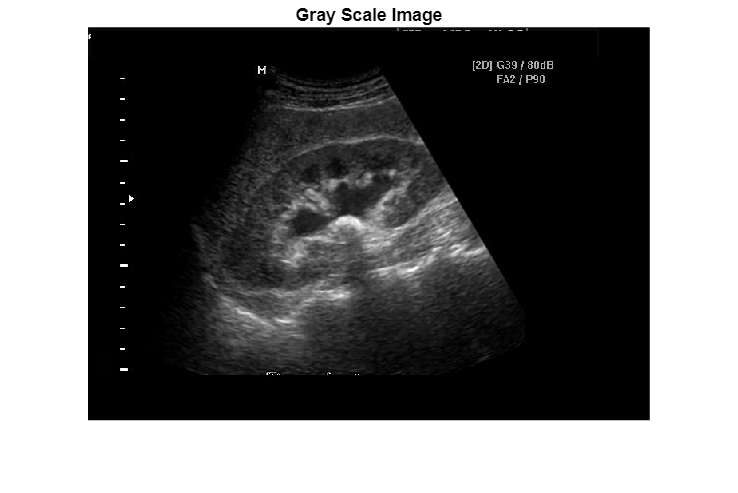

%Convert to grayscale image
rgbImg=rgb2gray(Img);
figure;
imshow(rgbImg);title("Gray Scale Image");

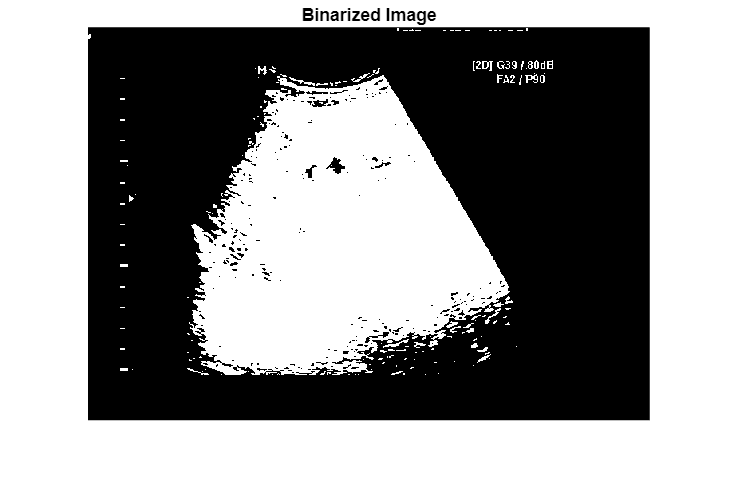

% Binarise the image
binImg=rgbImg>20;%Value greater than 20 will be 1
figure;
imshow(binImg);title("Binarized Image");

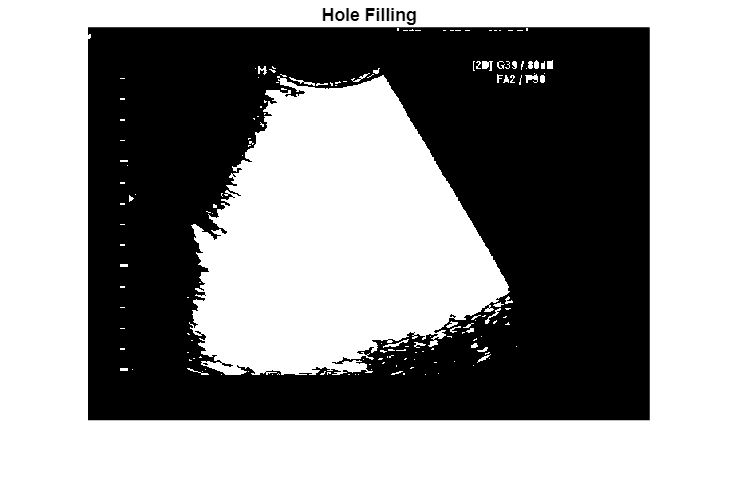

%Fill the holes present in region of interese
Img2=imfill(binImg,'holes');
figure;
imshow(Img2);title("Hole Filling");

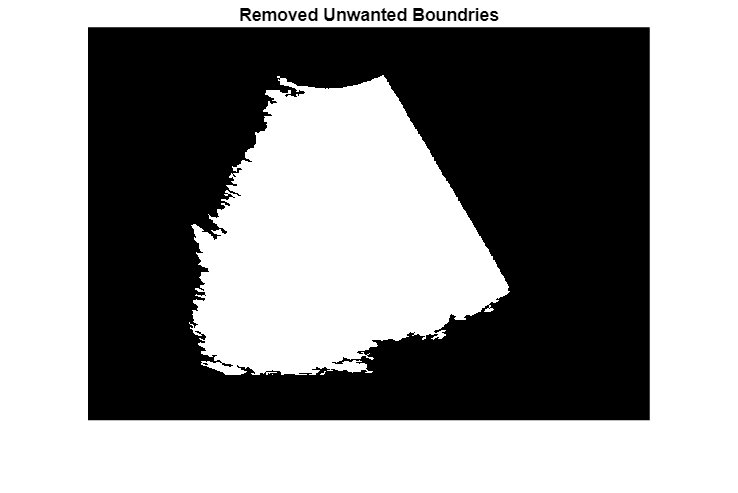

%Remove unnecessary boundry binary objects
Img3=bwareaopen(Img2,1000);
figure;
imshow(Img3);title("Removed Unwanted Boundries");

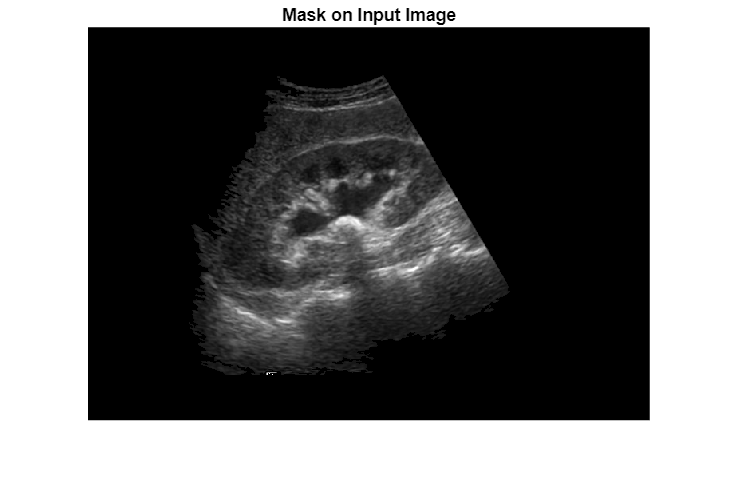

%Apply binary mask generated in image4 on original image
PreprocessedImage=uint8(double(Img).*repmat(Img3,[1 1 3]));
figure;
imshow(PreprocessedImage);title("Mask on Input Image");

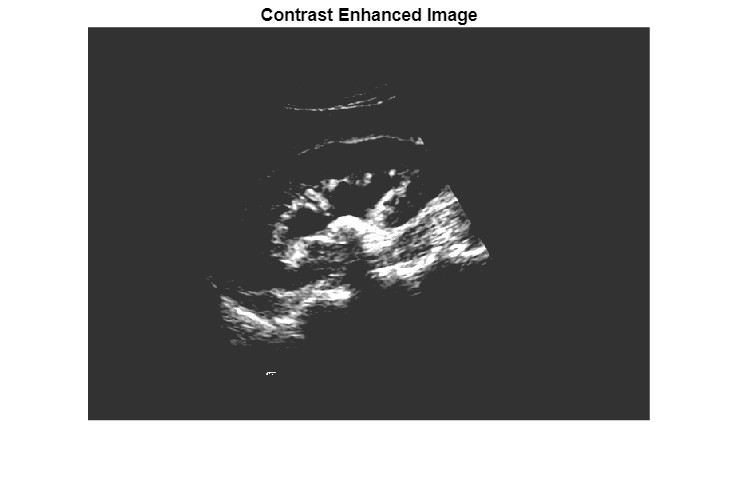

%apply contrast enhancement(pixel value below 0.3 treated as 0 and above
%0.7 treated as 1 and from 0.3 to 0.7 mapped to 0 to 1) 
PreprocessedImage=imadjust(PreprocessedImage,[0.3 0.7],[])+50;
figure;
imshow(PreprocessedImage);title("Contrast Enhanced Image");

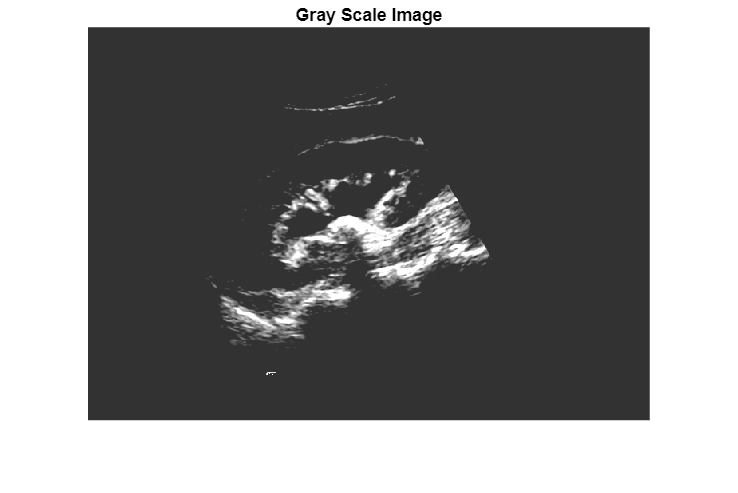

%Convert to grayscale image
PreprocessedImage1=rgb2gray(PreprocessedImage);
figure;
imshow(PreprocessedImage1);title("Gray Scale Image");

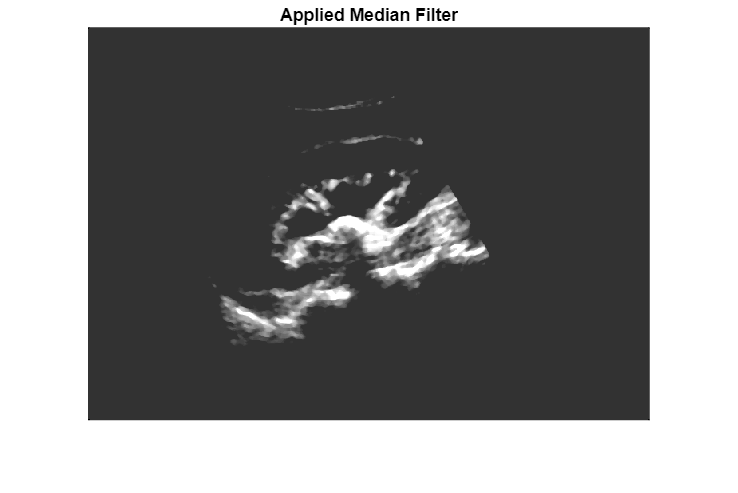

%remove isolated unnecessary binary objects around region of interest
PreprocessedImage2=medfilt2(PreprocessedImage1,[5 5]);
figure;
imshow(PreprocessedImage2);title("Applied Median Filter");

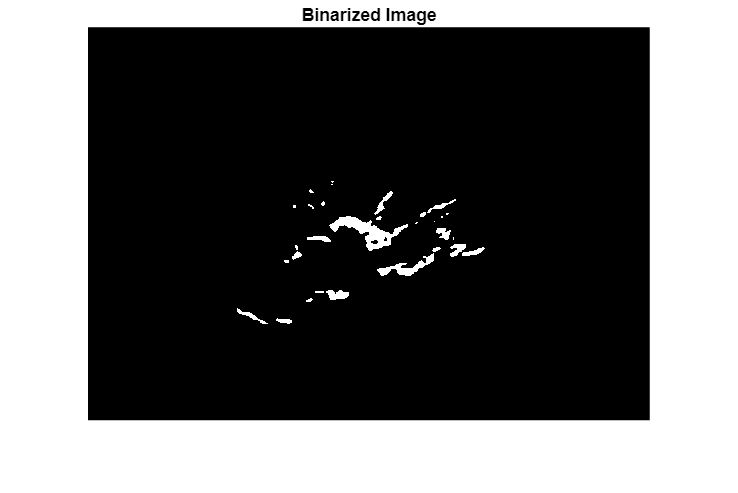

%thresholding the image with very high value to get exact object we want
PreprocessedImage3=PreprocessedImage2>230;
figure;
imshow(PreprocessedImage3);title("Binarized Image");

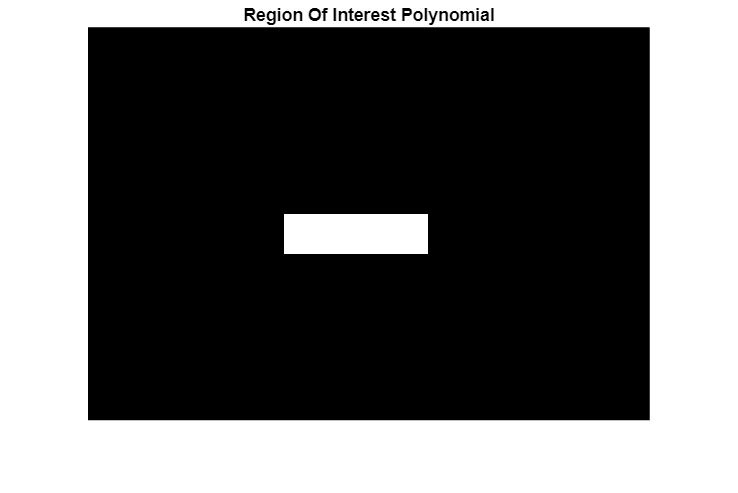

%using region of interest polynomial filter only middle part of kidney by masking image with generated polynomial

%creating region of interest polynomial(structuring element)

[r c]=size(PreprocessedImage3);
x1=r/2;
y1=c/3;
row=[x1 x1+180 x1+180 x1];
col=[y1 y1 y1+50 y1+50];
BWImg=roipoly(PreprocessedImage3,row,col);
figure;
imshow(BWImg);title("Region Of Interest Polynomial");

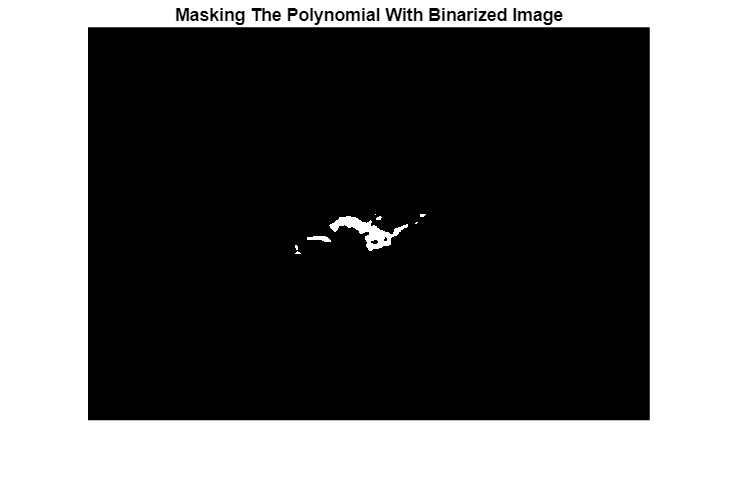

%mask this polynomial with BWImg
maskedImg=PreprocessedImage3.*double(BWImg);figure();
imshow(maskedImg);title("Masking The Polynomial With Binarized Image");

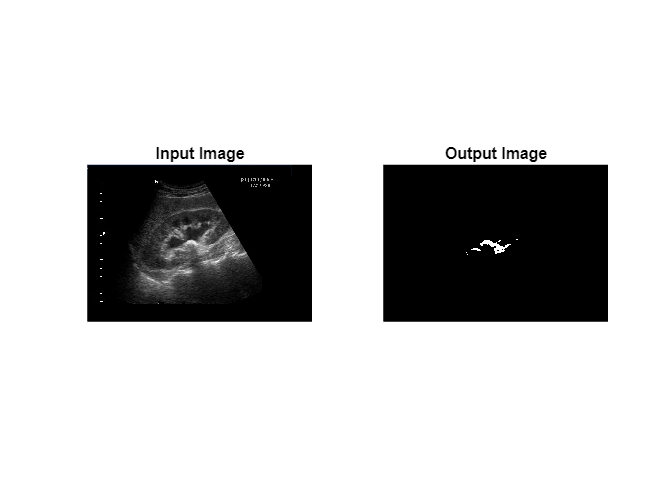

figure;
subplot(121);imshow(Img);title("Input Image");
subplot(122);imshow(maskedImg);title("Output Image");

%printing the result
finalImg=bwareaopen(maskedImg,4);
[ya number]=bwlabel(finalImg);
if(number>=1)
    disp('Stone is Detected');
else
    disp('No Stone is detected');
end

Stone is Detected


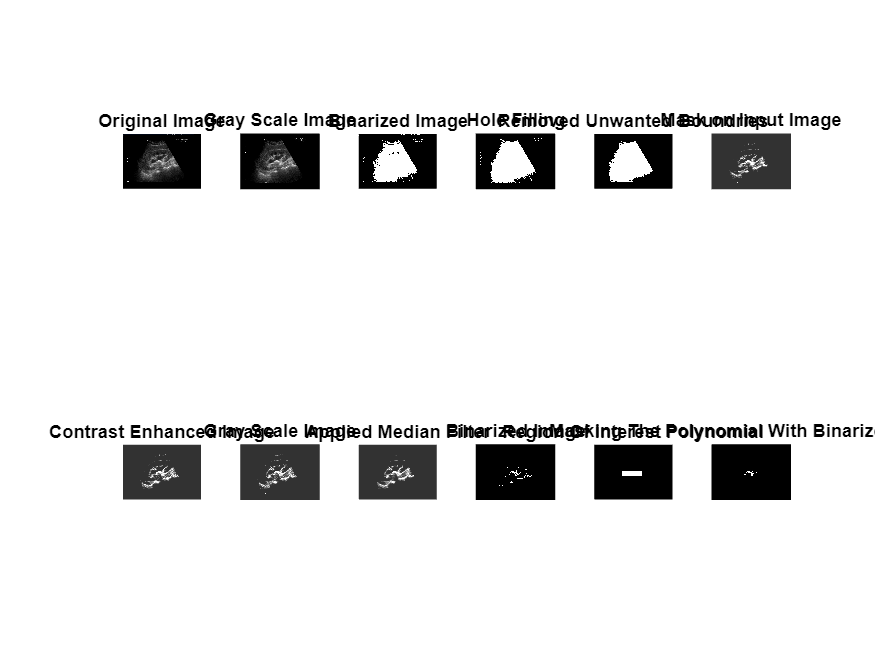

figure();
subplot(261);imshow(Img);title("Original Image");
subplot(262);imshow(rgbImg);title("Gray Scale Image");
subplot(263);imshow(binImg);title("Binarized Image");
subplot(264);imshow(Img2);title("Hole Filling");
subplot(265);imshow(Img3);title("Removed Unwanted Boundries");
subplot(266);imshow(PreprocessedImage);title("Mask on Input Image");
subplot(267);imshow(PreprocessedImage);title("Contrast Enhanced Image");
subplot(268);imshow(PreprocessedImage1);title("Gray Scale Image");
subplot(269);imshow(PreprocessedImage2);title("Applied Median Filter");
subplot(2,6,10);imshow(PreprocessedImage3);title("Binarized Image");
subplot(2,6,11);imshow(BWImg);title("Region Of Interest Polynomial");
subplot(2,6,12);imshow(maskedImg);title("Masking The Polynomial With Binarized Image");